Read the table

table = readtable('quat_align_IMUright.csv')

table = 1500×5 table
    Time_s_        W           X            Y             Z     
    ________    _______    _________    __________    __________

    0.010829    0.99594    -0.068612    -0.0035813    -0.0041621
    0.030651    0.99594    -0.068617    -0.0035794    -0.0042288
    0.050472    0.99594    -0.068615    -0.0035964    -0.0042833
    0.070292    0.99594    -0.068612    -0.0035948    -0.0043305
    0.090113    0.99594    -0.068618    -0.0035964    -0.0043836
     0.10993    0.99593    -0.068626    -0.0036097    -0.0044413
     0.12976    0.99594      -0.0686    -0.0035982    -0.0044545
     0.14958    0.99594    -0.068594     -0.003601    -0.0044453
      0.1694    0.99594      -0.0686    -0.0035946    -0.0044503
     0.18922    0.99594    -0.068602    -0.0035993    -0.0044347
     0.20903    0.99594    -


q0 = table(:, 'W');
q1 = table(:, 'X');
q2 = table(:, 'Y');
q3 = table(:, 'Z');
T = table(:, 'Time_s_');

Transforming table to quaternions array

q0 = table2array(q0);
q1 = table2array(q1);
q2 = table2array(q2);
q3 = table2array(q3);
T = table2array(T);

quat = [q0, q1, q2, q3];

Quaternions to Euler's angles

eulZYX = quat2eul(quat) 

eulZYX =    -0.0078   -0.0077   -0.1375
   -0.0080   -0.0077   -0.1375
   -0.0081   -0.0078   -0.1375
   -0.0082   -0.0078   -0.1375
   -0.0083   -0.0078   -0.1375
   -0.0084   -0.0078   -0.1376
   -0.0084   -0.0078   -0.1375
   -0.0084   -0.0078   -0.1375
   -0.0084   -0.0078   -0.1375
   -0.0084   -0.0078   -0.1375


Z = eulZYX(:, 1)

Z =    -0.0078
   -0.0080
   -0.0081
   -0.0082
   -0.0083
   -0.0084
   -0.0084
   -0.0084
   -0.0084
   -0.0084


Y = eulZYX(:, 2)

Y =    -0.0077
   -0.0077
   -0.0078
   -0.0078
   -0.0078
   -0.0078
   -0.0078
   -0.0078
   -0.0078
   -0.0078


X = eulZYX(:, 3)

X =    -0.1375
   -0.1375
   -0.1375
   -0.1375
   -0.1375
   -0.1376
   -0.1375
   -0.1375
   -0.1375
   -0.1375


Plot graphics

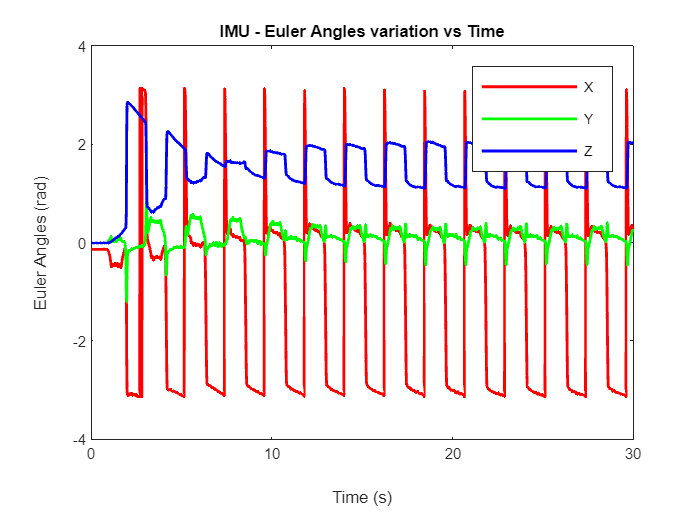

plot(T, X, "r-", 'LineWidth', 1.7)
title("IMU - Euler Angles variation vs Time")
xlabel("Time (s)")
ylabel("Euler Angles (rad)")


hold on
plot(T, Y, "g-", 'LineWidth', 1.7)
plot(T, Z, "b-", 'LineWidth', 1.7)
hold off

legend('X', 'Y', 'Z')

Read the table - Misalignment

tablem = readtable('quat_misalign_idler3right_IMUright.csv')

tablem = 1501×5 table
    Time_s_        W           X           Y           Z   
    ________    _______    _________    ________    _______

    0.010428    0.93816    -0.078031    0.031518    0.33075
    0.030252    0.93811    -0.078036    0.031527     0.3309
    0.050074    0.93805    -0.078037    0.031531    0.33107
    0.069897      0.938    -0.078045    0.031546     0.3312
     0.08972    0.93796    -0.078071     0.03154    0.33131
     0.10954    0.93793    -0.078061    0.031551    0.33139
     0.13184    0.93792    -0.078065    0.031548    0.33142
     0.15167    0.93791     -0.07806    0.031561    0.33145
     0.17149    0.93792    -0.078043    0.031567    0.33142
     0.19131    0.93793    -0.078039    0.031571    0.33141
     0.21113    0.93792    -0.078038    0.031575    0.33144
     0.23095    0.93789    


q0m = tablem(:, 'W');
q1m = tablem(:, 'X');
q2m = tablem(:, 'Y');
q3m = tablem(:, 'Z');
Tm = tablem(:, 'Time_s_');

Transforming table to quaternions array - Misalignment

q0m = table2array(q0m);
q1m = table2array(q1m);
q2m = table2array(q2m);
q3m = table2array(q3m);
Tm = table2array(Tm);

quatm = [q0m, q1m, q2m, q3m];

Quaternions to Euler's angles - Misalignment

eulZYXm = quat2eul(quatm) 

eulZYXm =     0.6708    0.1114   -0.1271
    0.6711    0.1114   -0.1271
    0.6715    0.1114   -0.1271
    0.6718    0.1115   -0.1271
    0.6720    0.1115   -0.1271
    0.6722    0.1115   -0.1271
    0.6722    0.1115   -0.1271
    0.6723    0.1116   -0.1271
    0.6722    0.1116   -0.1270
    0.6722    0.1116   -0.1270


Zm = eulZYXm(:, 1)

Zm =     0.6708
    0.6711
    0.6715
    0.6718
    0.6720
    0.6722
    0.6722
    0.6723
    0.6722
    0.6722


Ym = eulZYXm(:, 2)

Ym =     0.1114
    0.1114
    0.1114
    0.1115
    0.1115
    0.1115
    0.1115
    0.1116
    0.1116
    0.1116


Xm = eulZYXm(:, 3)

Xm =    -0.1271
   -0.1271
   -0.1271
   -0.1271
   -0.1271
   -0.1271
   -0.1271
   -0.1271
   -0.1270
   -0.1270


Plot graphics 

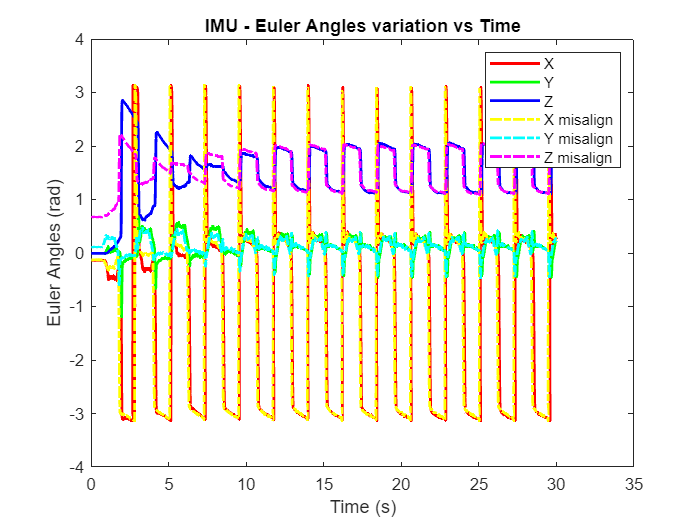

plot(T, X, "r-", 'LineWidth', 1.7)
title("IMU - Euler Angles variation vs Time")
xlabel("Time (s)")
ylabel("Euler Angles (rad)")


hold on
plot(T, Y, "g-", 'LineWidth', 1.7)
plot(T, Z, "b-", 'LineWidth', 1.7)
plot(Tm, Xm, "y-.", 'LineWidth', 1.7)
plot(Tm, Ym, "c-.", 'LineWidth',1.7)
plot(Tm, Zm, "m-.", 'LineWidth', 1.7)
hold off

legend('X', 'Y', 'Z', 'X misalign', 'Y misalign', 'Z misalign')